# Preprocessing of Neuropixels recordings in the flight room

- Recording date: 2/7/2024

- Recording method: untethered recording in the flight room.

- Experiment setup: multiple bats (n=10) were flew in the flight room simultaneously. Two bats (14633 and 14662) were recorded for their neural activity.

- Target region of ephys recording: 14633 and 14662 was implanted with two probes respectively. For 14633, the probe 1 was targetting the dorsal/ventral hippocampus and the probe 2 was targetting the mEC. For 14662, the probe 1 was targetting the hippocampus and the mEC and the probe 2 was targetting the dorsal and ventral hippocampus.

- Feeder: feeder 1 and 2 was activated with a banana smoothie syringe.

## Recording information (Edit here)

rec_date = '240207'; % recording date
rec_type = 'untethered'; % recording type
exp_type = 'flight'; % experiment type
data_dir = 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207'; % parent directory for all recordings
cd(data_dir)

% Bat subjects
bname = {"14447","11827","29924","14406","14561","14633","14662","14531","71050","9776"}; % in order of serial number list
bname_ephys = {'14633','14662'}; % ephys bat

% reward
reward_list = {"banana","pear","grape","melon"};
reward_session = [1,1,0,0; 1,1,0,0];
save('exp_info.mat','rec_date','rec_type','exp_type','bname','bname_ephys','reward_list','reward_session')


### Directory to ouput the results

% output directory
res_dir_path     =   fullfile(data_dir,'analysis');
if isempty(dir(res_dir_path))
    mkdir(res_dir_path)
end
% Figure
fig_dir_path    =   fullfile(res_dir_path,'figure');
if isempty(dir(fig_dir_path))
    mkdir(fig_dir_path)
end

## Preprocessing of Neuropixels data

### Extracting LFP, spikeband, and other data types    

trodes_path = 'C:\Users\Tatsumi\Documents\Trodes\Trodes_2-5-0_Windows64'; % trodes 2.5.0
exportAllTrodesRecordingsAllBats(data_dir,trodes_path,'isTethered',0); % extract LFP, spikeband, kilosort dat, etc. from the raw data for all bats

Extracting data from Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14633 

trodesexport -lfp -analogio -kilosort -dio -spikes -spikeband -time -lfplowpass 500 -lfpoutputrate 1500 -uselfpfilters 0 -spikehighpass 600 -spikelowpass 6000 -usespikefilters 0 -invert 0 -rec "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14633\20240207_103632_merged.rec" -outputdirectory "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14633" -interp 0
Using the following workspace file:  "20240207_103632_merged.trodesconf"
Exporting data...
1.092%2.183%3.275%4.366%5.458%6.549%A gap of 513 packets occured in the file. Last timestamp:  15806085 (Clock is:  "00:08:46" )
A gap of 514 packets occured in the file. Last timestamp:  15811550 (Clock is:  "00:08:47" )
A gap of 514 packets occured in the file. Last timestamp:  15817016 (Clock is:  "00:08:47" )
A gap of 515 packets occured in the file.

chanmap_file = struct with fields:
       name: '20240207_103632_merged.channelmap_probe1.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14633\20240207_103632_merged.kilosort'
       date: '09-Feb-2024 22:44:47'
      bytes: 5253
      isdir: 0
    datenum: 7.3929e+05


Extracting data from Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662 

trodesexport -lfp -analogio -kilosort -dio -spikes -spikeband -time -lfplowpass 500 -lfpoutputrate 1500 -uselfpfilters 0 -spikehighpass 600 -spikelowpass 6000 -usespikefilters 0 -invert 0 -rec "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662\20240207_103632_merged.rec" -outputdirectory "Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662" -interp 0
Using the following workspace file:  "20240207_103632_merged.trodesconf"
Exporting data...
A gap of 282 packets occured in the file. Last timestamp:  5216867 (Clock is:  "00:02:53" )
1.085%2.17%3.255%A gap of 4 packets occured in the file. Last timestamp:  10306457 (Clock is:  "00:05:43" )
A gap of 169 packets occured in the file. Last timestamp:  10708103 (Clock is:  "00:05:56" )
4.339%A gap of 45 packets occured in the file. Last timestamp: 

chanmap_file = struct with fields:
       name: '20240207_103632_merged.channelmap_probe1.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662\20240207_103632_merged.kilosort'
       date: '10-Feb-2024 00:32:02'
      bytes: 2757
      isdir: 0
    datenum: 7.3929e+05


chanmap_file = struct with fields:
       name: '20240207_103632_merged.channelmap_probe2.dat'
     folder: 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662\20240207_103632_merged.kilosort'
       date: '10-Feb-2024 00:32:02'
      bytes: 3333
      isdir: 0
    datenum: 7.3929e+05


### Run kilosort

Looking for data inside Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14633\20240207_103632_merged.kilosort 


errString = 'kilosort repo not found, or inaccessible.'

Time   0s. Computing whitening matrix.. 
Getting channel whitening matrix... 
Channel-whitening matrix computed. 
Time  22s. Loading raw data and applying filters... 
Time 568s. Finished preprocessing 1257 batches. 
vertical pitch size is 20 
horizontal pitch size is 16 
   -24   -16    -8     0     8    16    24

        1534

0.43 sec, 1 batches, 10000 spikes 
40.62 sec, 101 batches, 1010000 spikes 
85.22 sec, 201 batches, 2009290 spikes 
130.85 sec, 301 batches, 3009290 spikes 
179.72 sec, 401 batches, 4007813 spikes 
231.99 sec, 501 batches, 4998014 spikes 
287.53 sec, 601 batches, 5993580 spikes 
346.58 sec, 701 batches, 6991129 spikes 
408.96 sec, 801 batches, 7971992 spikes 
474.82 sec, 901 batches, 8956278 spikes 
544.04 sec, 1001 batches, 9943338 spikes 
619.09 sec, 1101 batches, 10937988 spikes 
700.25 sec, 1201 batches, 11936176 spikes 
746.36 sec, 1257 batches, 12488979 spikes 


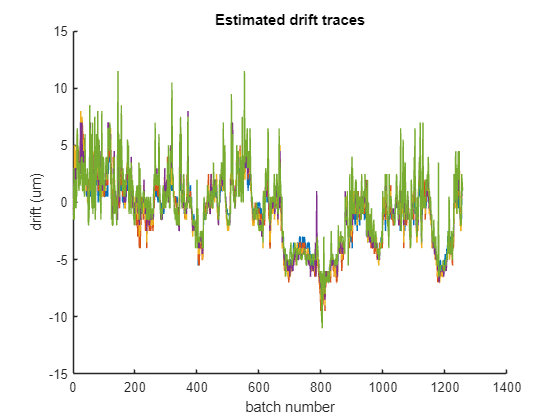

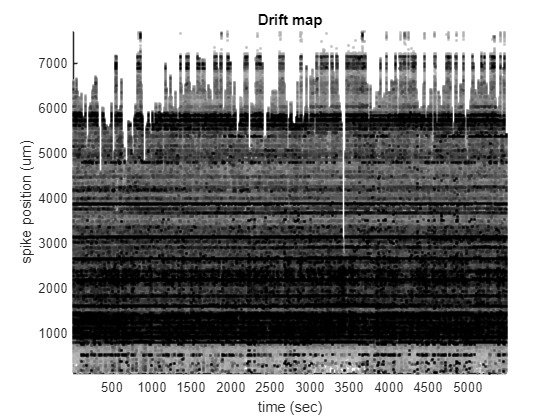

time 1850.22, Shifted up/down 1257 batches. 
0.92 sec, 1 batches, 10000 spikes 
90.93 sec, 101 batches, 1010000 spikes 
180.71 sec, 201 batches, 2010000 spikes 
270.50 sec, 301 batches, 3010000 spikes 
360.48 sec, 401 batches, 4010000 spikes 
452.84 sec, 501 batches, 5010000 spikes 
546.09 sec, 601 batches, 6010000 spikes 
636.71 sec, 701 batches, 7010000 spikes 
728.11 sec, 801 batches, 8010000 spikes 
819.01 sec, 901 batches, 9010000 spikes 
912.42 sec, 1001 batches, 10010000 spikes 
1003.59 sec, 1101 batches, 11010000 spikes 
1095.50 sec, 1201 batches, 12010000 spikes 
1146.37 sec, 1257 batches, 12570000 spikes 
time 0.00, GROUP 1/384, units 0 
time 2.43, GROUP 6/384, units 10 
time 4.71, GROUP 11/384, units 21 
time 6.25, GROUP 16/384, units 28 
time 9.77, GROUP 21/384, units 40 
time 19.80, GROUP 26/384, units 68 
time 25.68, GROUP 31/384, units 84 
time 30.30, GROUP 36/384, units 97 
time 33.54, GROUP 41/384, units 106 
time 36.03, GROUP 46/384, units 112 
time 40.01, GROUP 51/38

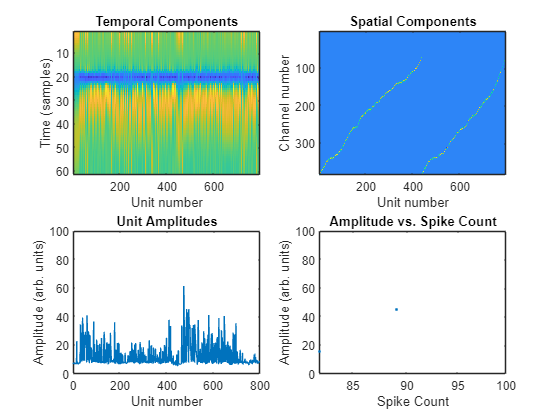

time 0.00, GROUP 1/384, units 0 
time 0.02, GROUP 6/384, units 0 
time 0.04, GROUP 11/384, units 0 
time 0.06, GROUP 16/384, units 0 
time 0.08, GROUP 21/384, units 0 
time 0.09, GROUP 26/384, units 0 
time 0.11, GROUP 31/384, units 0 
time 0.13, GROUP 36/384, units 0 
time 0.15, GROUP 41/384, units 0 
time 0.16, GROUP 46/384, units 0 
time 0.18, GROUP 51/384, units 0 
time 0.19, GROUP 56/384, units 0 
time 0.21, GROUP 61/384, units 0 
time 0.22, GROUP 66/384, units 0 
time 0.24, GROUP 71/384, units 0 
time 0.26, GROUP 76/384, units 0 
time 0.27, GROUP 81/384, units 0 
time 0.29, GROUP 86/384, units 0 
time 0.30, GROUP 91/384, units 0 
time 0.31, GROUP 96/384, units 0 
time 11.37, GROUP 101/384, units 22 
time 20.41, GROUP 106/384, units 37 
time 26.57, GROUP 111/384, units 48 
time 35.36, GROUP 116/384, units 62 
time 42.83, GROUP 121/384, units 72 
time 54.28, GROUP 126/384, units 88 
time 59.56, GROUP 131/384, units 95 
time 69.66, GROUP 136/384, units 109 
time 90.19, GROUP 141/384

ans = 160

initialized spike counts
merged 370 into 369 
merged 420 into 424 
merged 415 into 413 
merged 259 into 240 
merged 4 into 8 
merged 1 into 8 
merged 382 into 380 
merged 234 into 231 
merged 237 into 239 
merged 245 into 238 
merged 30 into 29 
merged 457 into 452 
merged 122 into 118 
merged 129 into 130 
merged 248 into 257 
merged 258 into 253 
merged 256 into 240 
merged 225 into 219 
merged 376 into 368 
merged 336 into 338 
merged 349 into 352 
merged 250 into 254 
merged 221 into 211 
merged 383 into 374 
merged 254 into 261 
merged 351 into 348 
merged 38 into 37 
merged 362 into 365 
merged 271 into 275 
merged 116 into 114 
merged 372 into 375 
merged 462 into 459 
merged 328 into 330 


ans = 144

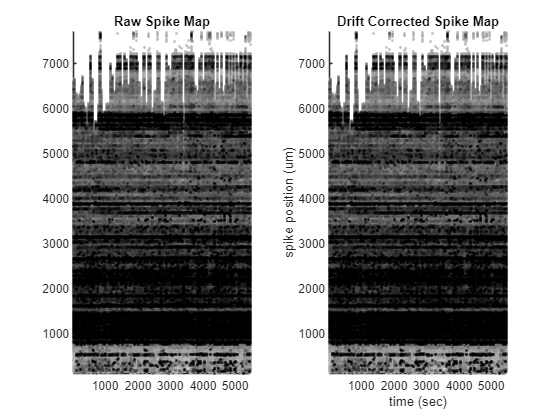

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [384×1 double]
                 yc: [384×1 double]
            xcoords: [384×1 double]
            ycoords: [384×1 double]
               Wrot: [384×384 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×384 gpuArray]
               dist: [10×3452 single]
              iorig: [1257×1 double]
             dshift: [1257×5 double]
                st0: [12488979×6 double]
                  F: [1534×20×1257 double]
                 F0: [1534×20 gpuArray]
                F0m: [1534×20 gpuArray]
               ycup: [100 100 100 100 100 110 110 110 110 110 120 120 120 130 130 130 130 130 140 140 140 140 140 150 150 150 150 150 160 160 160 170 170 170 170 170 180 180 180 180 180 190 190 190 190 190 200 200 200 210 210 210 210 … ] (1×3452 double)
               xcup: [-8 0 8 16 24 -8 0 8 16 24 8 16 24 -8 0 8 16 24 -8 0 8 16 24 -8 

Looking for data inside Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662\20240207_103632_merged.kilosort 


errString = 'kilosort repo not found, or inaccessible.'

Time   0s. Computing whitening matrix.. 
Getting channel whitening matrix... 
Channel-whitening matrix computed. 
Time   7s. Loading raw data and applying filters... 
Time 168s. Finished preprocessing 580 batches. 
vertical pitch size is 20 
horizontal pitch size is 16 
   -24   -16    -8     0     8    16    24

        1350

0.18 sec, 1 batches, 6864 spikes 
19.21 sec, 101 batches, 551494 spikes 
38.71 sec, 201 batches, 1090019 spikes 
59.72 sec, 301 batches, 1559478 spikes 
82.58 sec, 401 batches, 2018892 spikes 
106.92 sec, 501 batches, 2363930 spikes 
127.33 sec, 580 batches, 2561986 spikes 


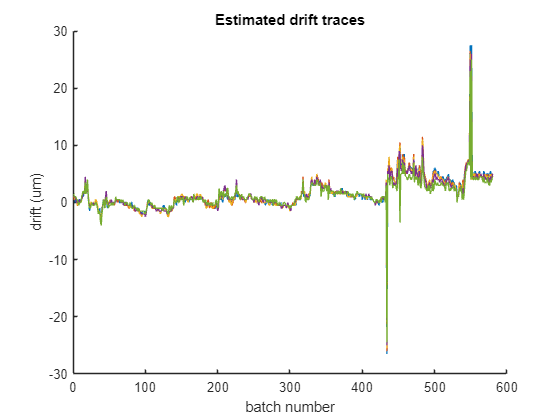

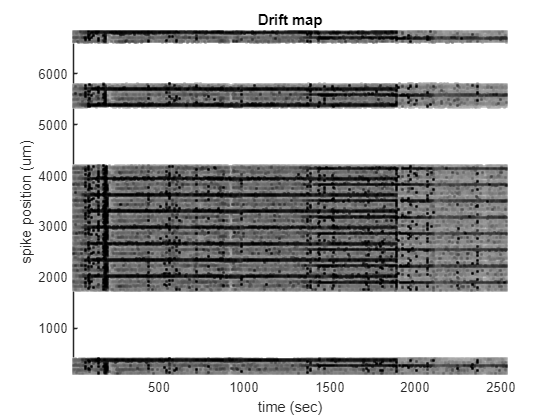

time 294.70, Shifted up/down 580 batches. 
0.24 sec, 1 batches, 10000 spikes 
23.41 sec, 101 batches, 938087 spikes 
46.69 sec, 201 batches, 1933415 spikes 
70.20 sec, 301 batches, 2890253 spikes 
93.41 sec, 401 batches, 3837273 spikes 
116.61 sec, 501 batches, 4557624 spikes 
135.31 sec, 580 batches, 5012263 spikes 
time 0.00, GROUP 1/338, units 0 
time 1.83, GROUP 6/338, units 8 
time 6.61, GROUP 11/338, units 27 
time 6.61, GROUP 16/338, units 27 
time 6.61, GROUP 21/338, units 27 
time 6.61, GROUP 26/338, units 27 
time 6.61, GROUP 31/338, units 27 
time 6.61, GROUP 36/338, units 27 
time 6.61, GROUP 41/338, units 27 
time 8.83, GROUP 46/338, units 36 
time 13.66, GROUP 51/338, units 51 
time 16.10, GROUP 56/338, units 59 
time 21.91, GROUP 61/338, units 77 
time 26.58, GROUP 66/338, units 92 
time 28.67, GROUP 71/338, units 99 
time 34.17, GROUP 76/338, units 116 
time 37.03, GROUP 81/338, units 125 
time 40.03, GROUP 86/338, units 135 
time 44.22, GROUP 91/338, units 148 
time 46

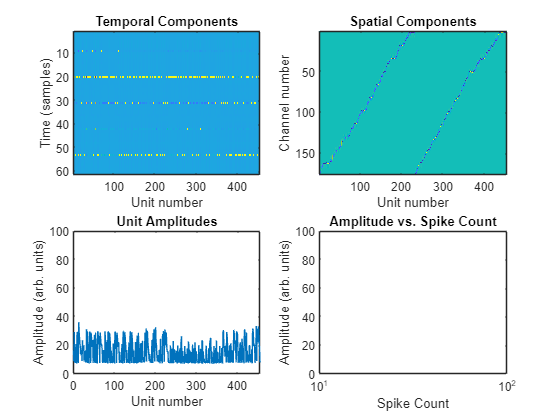

time 0.00, GROUP 1/338, units 0 
time 1.87, GROUP 6/338, units 8 
time 8.44, GROUP 11/338, units 29 
time 8.45, GROUP 16/338, units 29 
time 8.45, GROUP 21/338, units 29 
time 8.45, GROUP 26/338, units 29 
time 8.45, GROUP 31/338, units 29 
time 8.46, GROUP 36/338, units 29 
time 8.46, GROUP 41/338, units 29 
time 10.49, GROUP 46/338, units 36 
time 18.58, GROUP 51/338, units 60 
time 21.92, GROUP 56/338, units 71 
time 30.20, GROUP 61/338, units 99 
time 36.64, GROUP 66/338, units 119 
time 40.88, GROUP 71/338, units 134 
time 49.57, GROUP 76/338, units 162 
time 54.80, GROUP 81/338, units 178 
time 59.26, GROUP 86/338, units 193 
time 65.59, GROUP 91/338, units 214 
time 69.25, GROUP 96/338, units 226 
time 74.16, GROUP 101/338, units 244 
time 74.17, GROUP 106/338, units 244 
time 74.17, GROUP 111/338, units 244 
time 74.18, GROUP 116/338, units 244 
time 74.18, GROUP 121/338, units 244 
time 74.18, GROUP 126/338, units 244 
time 74.18, GROUP 131/338, units 244 
time 74.19, GROUP 13

ans = 34

initialized spike counts
merged 127 into 130 
merged 249 into 251 


ans = 33

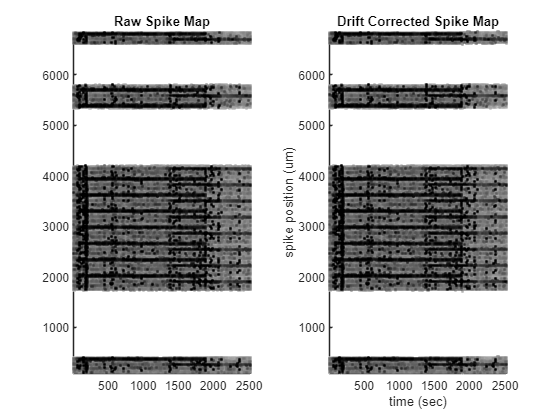

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [176×1 double]
                 yc: [176×1 double]
            xcoords: [176×1 double]
            ycoords: [176×1 double]
               Wrot: [176×176 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×176 gpuArray]
               dist: [10×1590 single]
              iorig: [580×1 double]
             dshift: [580×5 double]
                st0: [2561986×6 double]
                  F: [1350×20×580 double]
                 F0: [1350×20 gpuArray]
                F0m: [1350×20 gpuArray]
               ycup: [100 100 100 110 110 110 110 110 120 120 120 120 120 130 130 130 130 130 140 140 140 150 150 150 150 150 160 160 160 160 160 170 170 170 170 170 180 180 180 190 190 190 190 190 200 200 200 200 200 210 210 210 210 … ] (1×1590 double)
               xcup: [-24 -16 -8 -24 -16 -8 0 8 -24 -16 -8 0 8 -24 -16 -8 0 8 -24 -16 -8 

% 14633
path_to_rec_dir = 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14633'
probeNum = 1;
numChannels = 384;
runKilosort3(path_to_rec_dir,'probeNum',probeNum,'numChannels',numChannels)

% 14662
path_to_rec_dir = 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240207\ephys\20240207_103632.rec\14662'
probeNum = 1;
numChannels = 176;
runKilosort3(path_to_rec_dir,'probeNum',probeNum,'numChannels',numChannels)

probeNum = 2;
numChannels = 224;
runKilosort3(path_to_rec_dir,'probeNum',probeNum,'numChannels',numChannels)

disp('kilosort finished!')


## Preprocessing of cdp data

### Data directory

% cdp
cdp_dir = dir(fullfile(data_dir,'cdp','*cdp*.txt')); cdp_path = fullfile(cdp_dir.folder,cdp_dir.name);
% serial number
serial_dir = dir(fullfile(data_dir,'*Serial_numbers*')); serial_path = fullfile(serial_dir.folder,serial_dir.name);
% cortex
cortex_dir  =   dir(fullfile(data_dir,'cortex','*c3d'));
cortex_file =   fullfile(cortex_dir.folder,cortex_dir.name);
% reward
reward_dir  =   dir(fullfile(data_dir,'reward','*.mat'));

% experiment info
load('exp_info.mat')
n_session = size(reward_session,1);
reward_summary = cell(n_session,4);
for i = 1:n_session
    for fd = 1:4
        fl = reward_session(i,fd);
        if fl ~= 0
            reward_summary{i,fd} = reward_list{fl};
        end
    end
end
reward_summary

reward_summary = 1×4 cell array
    {'banana'}    {'banana'}    {0×0 double}    {0×0 double}


### Preprocess the cdp data

Extract the tag data from the raw cdp data by the *ExtractCdp* function. *sync_data(:,8)* is the timestamps interpolated based on the pseudo-Fibonacci TTLs. In this time vector, t=0 is the timing of the 1st pulse of the pseudo-Fibonacci TTLs. Make sure that this time vector will be shifted for 1.05 sec to set t=0 as the 1st pulse of the 3-sec TTLs.

                 Fs: 100
             tag_SN: [10×1 double]
            sync_SN: 17040920
               sync: 1
      sync_duration: 28.5297
       sync_samples: 171171
       tag_duration: [28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5306 28.5304]
        tag_samples: [170306 170252 170354 170276 170291 154435 170314 162235 170214 170279]
    tag_ac_duration: [28.5305 28.5304 28.5303 28.5304 28.5304 28.5304 28.5305 28.5305 28.5304 28.5304]
     tag_ac_samples: [170289 170309 172164 171475 172088 155443 172799 163493 172589 171176]
               tags: 10

All TTLs were detected, alignment OK
Sync: Fs (network time VS interpolated): 100Hz VS 98.12 Hz
Pos Tag1: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz


Pos Tag2: Fs (network time VS interpolated): 99.46 Hz VS 97.6 Hz


Pos Tag3: Fs (network time VS interpolated): 99.52 Hz VS 97.65 Hz


Pos Tag4: Fs (network time VS interpolated): 99.47 Hz VS 97.61 Hz


Pos Tag5: Fs (network time VS interpolated): 99.48 Hz VS 97.62 Hz


Pos Tag6: Fs (network time VS interpolated): 90.22 Hz VS 88.53 Hz


Pos Tag7: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz


Pos Tag8: Fs (network time VS interpolated): 94.77 Hz VS 93 Hz


Pos Tag9: Fs (network time VS interpolated): 99.43 Hz VS 97.57 Hz


Pos Tag10: Fs (network time VS interpolated): 99.47 Hz VS 97.61 Hz


Acc Tag1: Fs (network time VS interpolated): 99.48 Hz VS 97.62 Hz
Acc Tag2: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz
Acc Tag3: Fs (network time VS interpolated): 100.6 Hz VS 98.69 Hz
Acc Tag4: Fs (network time VS interpolated): 100.2 Hz VS 98.3 Hz
Acc Tag5: Fs (network time VS interpolated): 100.5 Hz VS 98.65 Hz
Acc Tag6: Fs (network time VS interpolated): 90.8 Hz VS 89.11 Hz
Acc Tag7: Fs (network time VS interpolated): 100.9 Hz VS 99.06 Hz
Acc Tag8: Fs (network time VS interpolated): 95.51 Hz VS 93.72 Hz
Acc Tag9: Fs (network time VS interpolated): 100.8 Hz VS 98.94 Hz
Acc Tag10: Fs (network time VS interpolated): 100 Hz VS 98.13 Hz


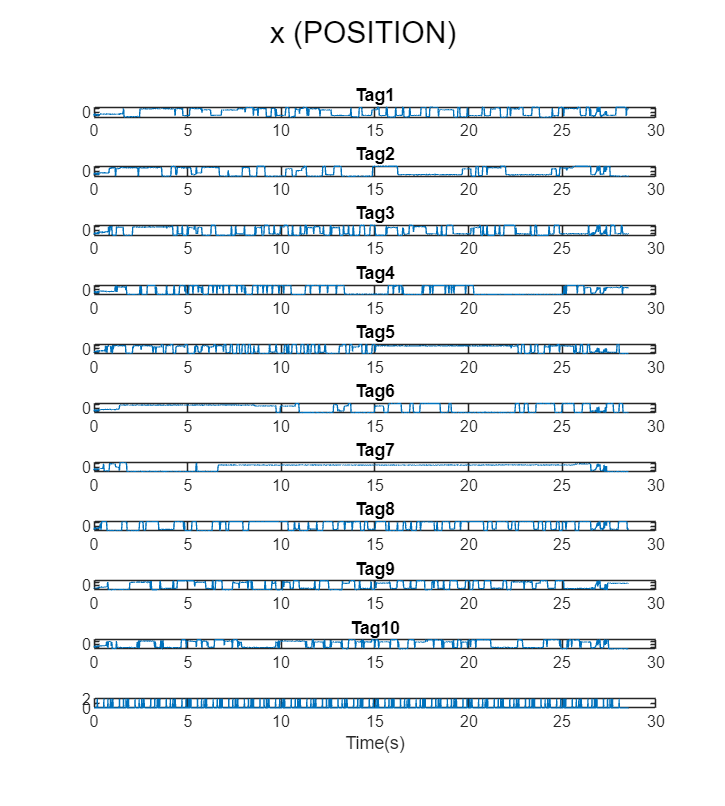

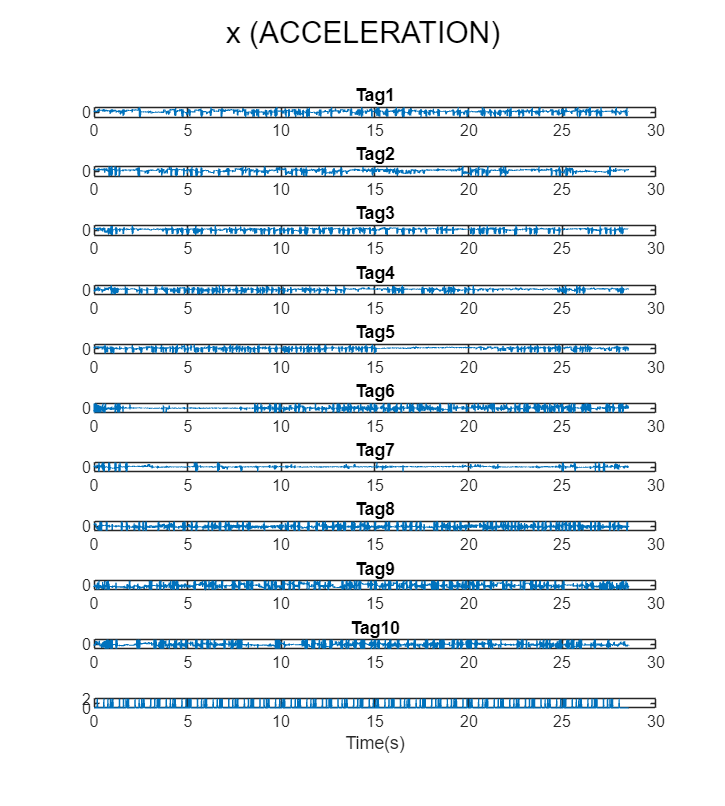

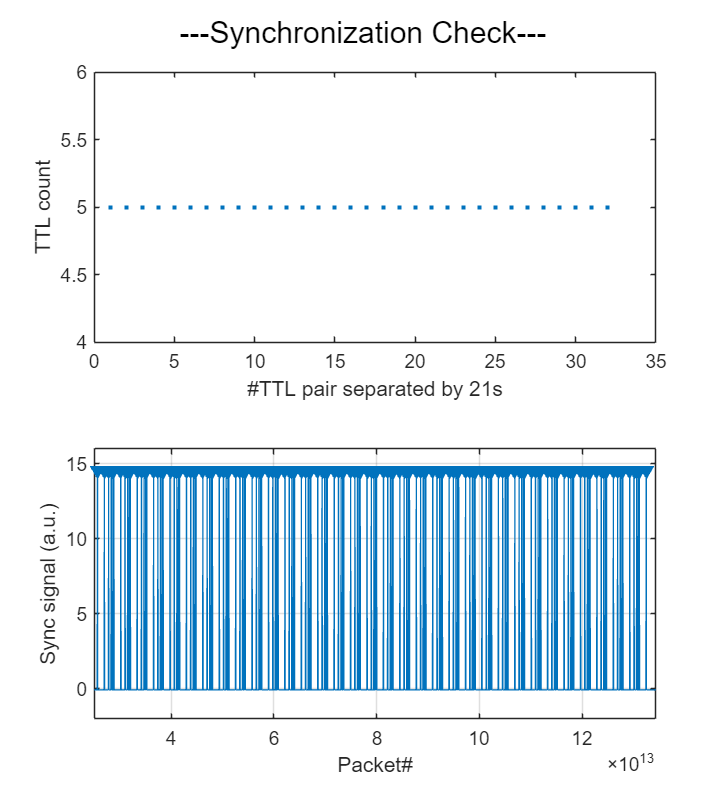

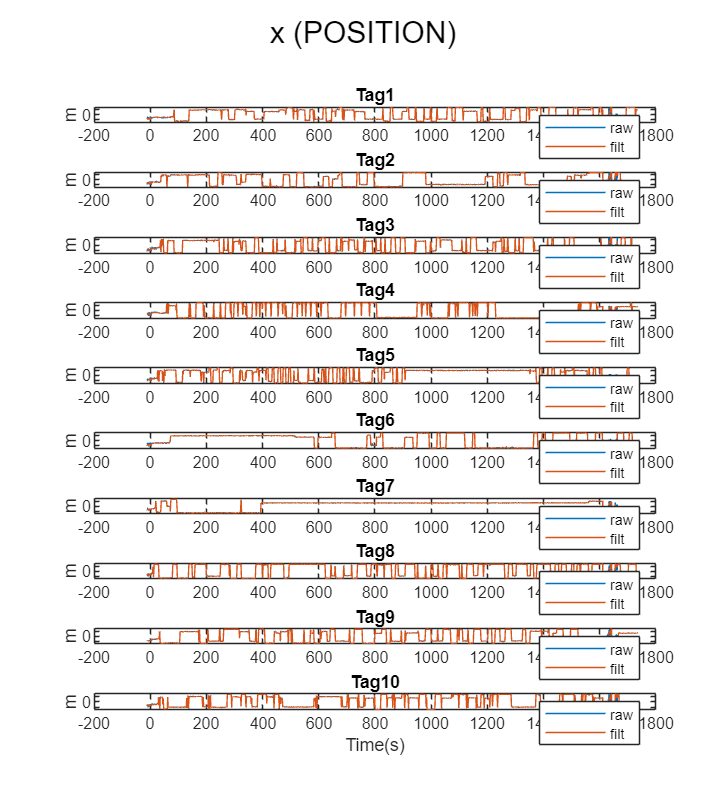

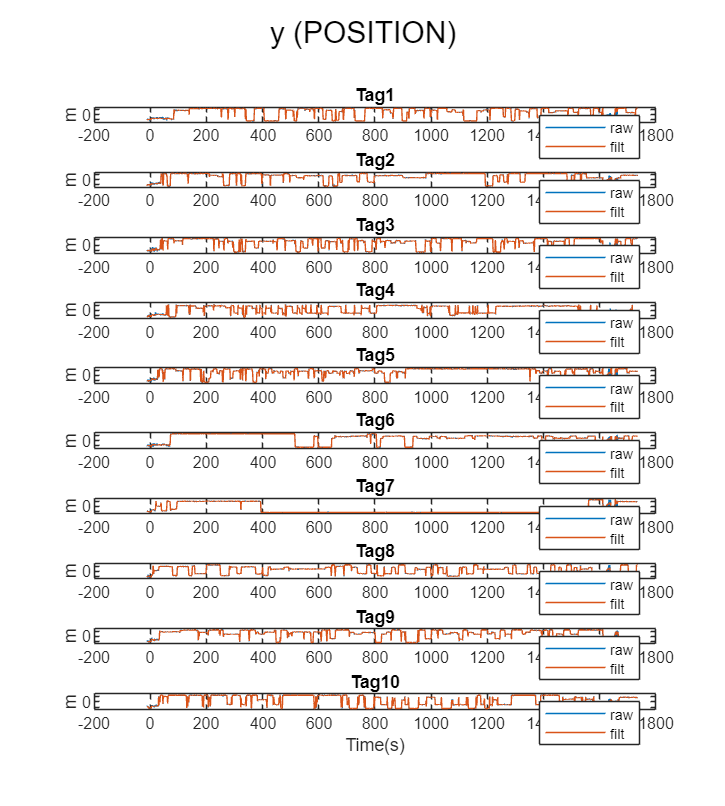

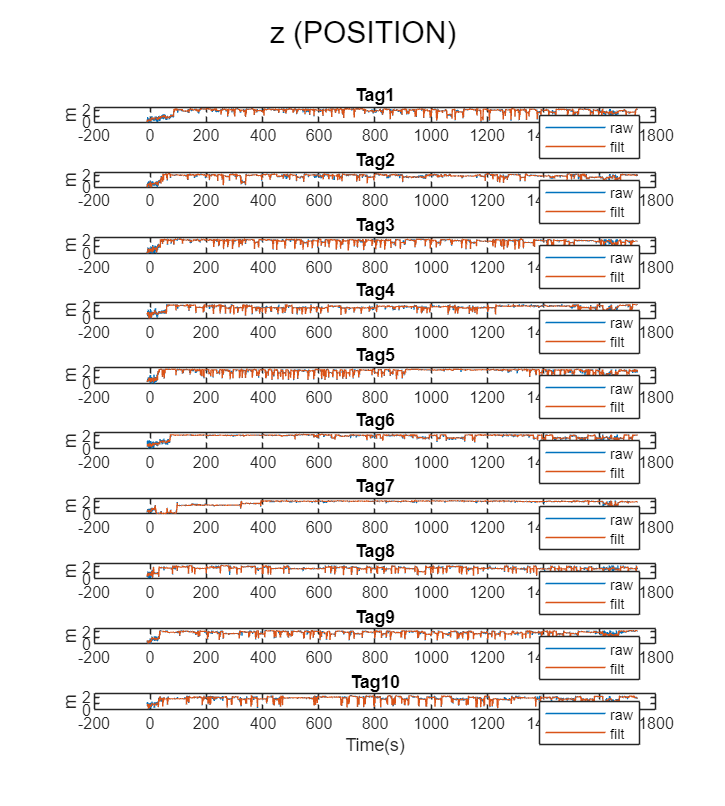

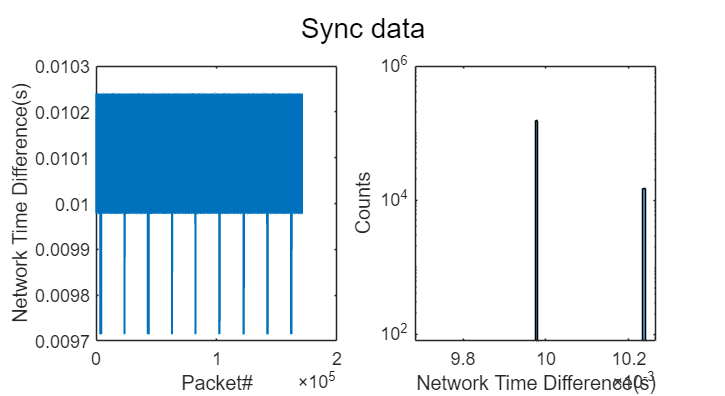

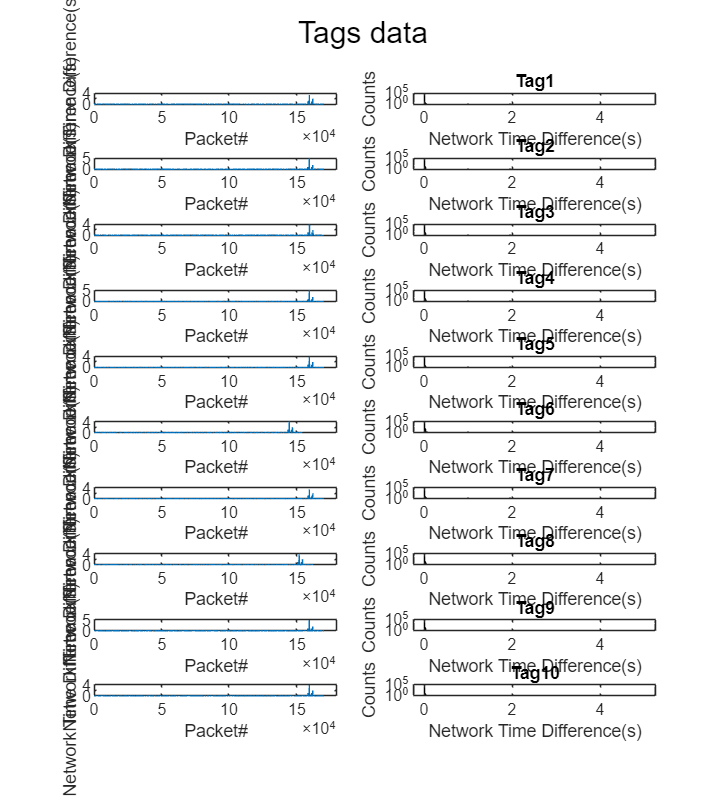

% Preprocess raw cdp data
cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*')); % raw cdp data
serial_number   =   load(serial_path); serial_number   =   serial_number'; % serial number of tags
if isempty(cdp_extracted)
    cd(cdp_dir.folder)
    ExtractCdp_AF_TY_v2('cdp',res_dir_path,'Include',serial_number) % Extract cdp data keeping the tag order
    cd(data_dir)
    % Load data
    cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*'));
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
elseif length(cdp_extracted) == 1
    disp('Extracted data are found in the directory.')
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
else
    error('Multiple files with the specified name were found. Check the file name.')
end

Output file is *extracted_YYMMDD_cdp_*.mat* under the "analysis" directory.

### Extract behavior data

The *Process_extracted_cdp* function extract behavioral features from the preprocessed data. The output is *Extracted_Behavior_YYMMDD.mat* under the "Ext_Behavior_YYMMDD_HHMM.mat" directory.

The variable *t* in the output file is the time vector for global time. The global time is set so that t=0 is the timing of the 1st 3-sec TTLs.

...Processing Ciholas Data...


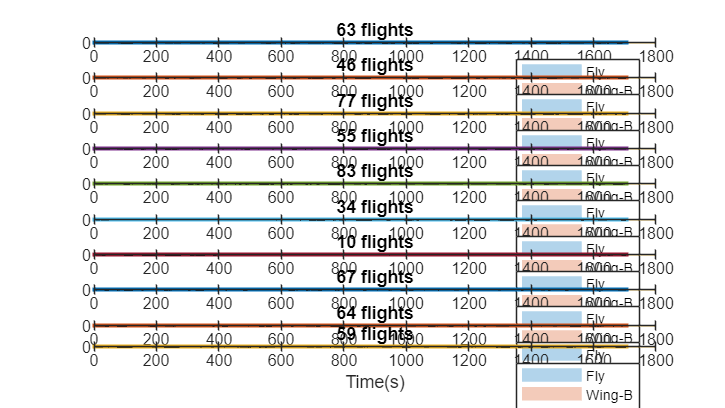

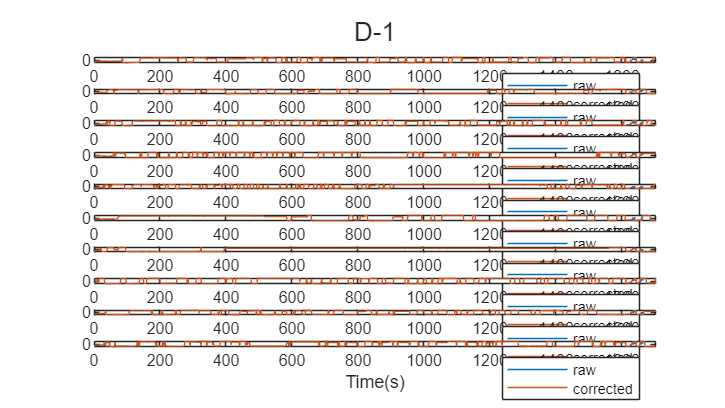

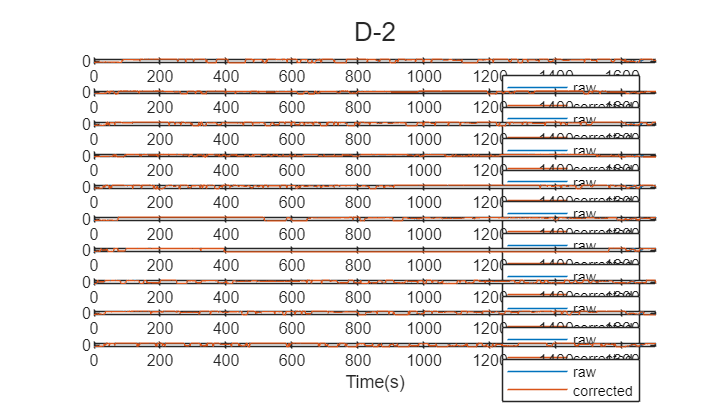

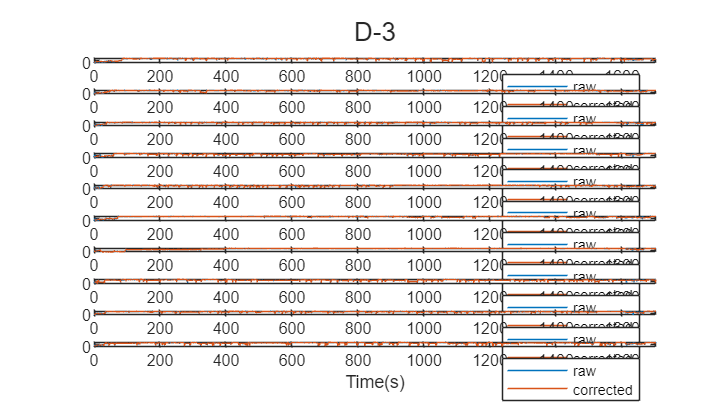

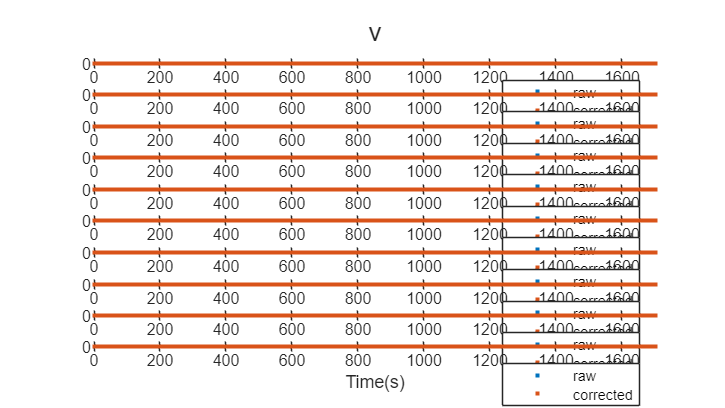

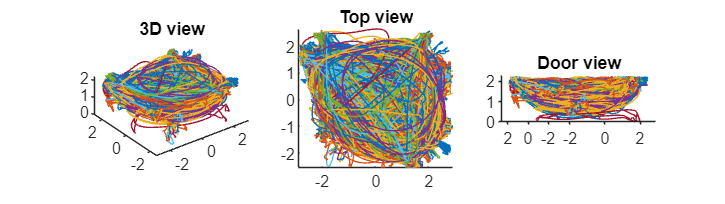

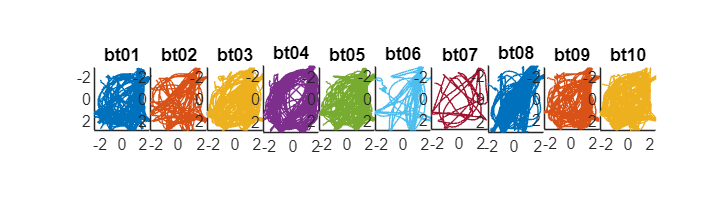

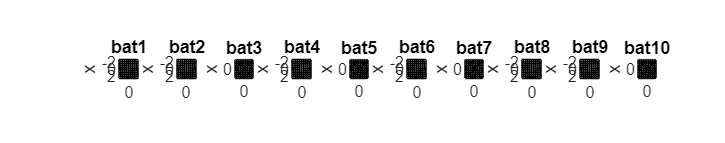

% Extract behaviors
beh_dir             =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
if isempty(beh_dir)
    cd(res_dir_path)
    Process_extracted_cdp_TY_v0(res_dir_path) % Extract behavioral features
    cd(data_dir)
    % Load data
    beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
    load(fullfile(beh_dir.folder,beh_dir.name))
elseif length(cdp_extracted) == 1
    disp('Behavior data are found in the directory.')
    load(fullfile(beh_dir.folder,beh_dir.name))
    disp('Behavior data are loaded.')
else
    error('Multiple files were contained in the directory. Check the file name.')
end

### Extract feeder data

The information related to reward provision is stored in the MATLAB files in the reward directory. These files contain the timings of reward provision, the identity of the bat who landed on feeders, the identity of feeders, etc.

#### Extracting sync signals

Extract the sync and reward information from the c3d file and save them into a MATLAB file.

% Extract synchronization and reward signals from c3d file
analog_dir = dir(fullfile(res_dir_path,'analog_signal.mat'));
if isempty(analog_dir)
    [~,~,AnalogSignals,AnalogFrameRate,~,~,~] = readC3D_analog(cortex_file); % read C3D data. Column 1 = reward, Column 2 = TTL, Column 3 = CDP server
elseif length(analog_dir)==1
    disp('Analog signal data are found.')
    load(fullfile(res_dir_path,'analog_signal.mat'),'AnalogSignals','AnalogFrameRate')
else
    error('Multiple files were contained in the directory. Check the file name.')
end
AnalogSignals = process_analog_signals(AnalogSignals,AnalogFrameRate);